# qRK Test **edits**

In this notebook, we're testing an implementation of tensor quantile randomized Kaczmarz.

addpath('../tproduct toolbox 2.0 (transform)/')

First, we'll generate a consistent tensor linear system.

l = 5;
p = 7;
n = 10;
m = 12;
num_corrupt = 1; % number of corruptions 
size_corrupt= 100; % size of corruptions 

%generate tensors
A = randn(m,l,n);
X_true = randn(l,p,n);

%generate consistent measurements
B = tprod(A,X_true);


Now, let's test the implementation of qRK.

%run some iterations of qRK
num_its = 1000;

%Try adding noise!
dims = prod(size(B));
ix_lin = randsample(dims,num_corrupt);



[ix_sub1, ix_sub2, ix_sub3] = ind2sub(size(B),ix_lin);
for i=1:num_corrupt
    % original line - corrupt 1 entry 
    B(ix_sub1(i),ix_sub2(i),ix_sub3(i)) = B(ix_sub1(i),ix_sub2(i),ix_sub3(i)) + size_corrupt;
end 



qv = 0.8 %quantile value

qv = 0.8000

[~,its] = qRK(A,B,randn(l,p,n),num_its); %quantile RK


%record errors
%errs = [];
errs = zeros(p,num_its+1)

errs =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0

errs_slice = zeros(l,n,num_its+1)

errs_slice = errs_slice(:,:,1) =

     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


errs_slice(:,:,2) =

     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


errs_slice(:,:,3) =

     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


err

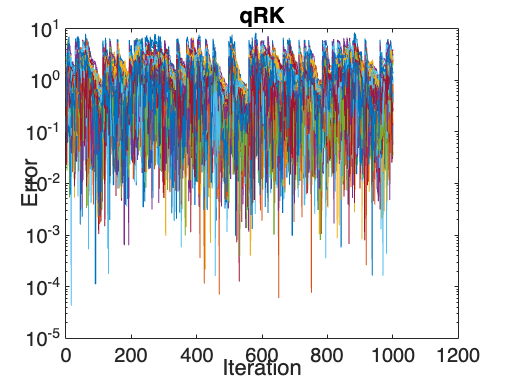

for j = 1:num_its+1
    errs_slice(:,:,j) = its{j}(:,ix_sub2,:) - X_true(:,ix_sub2,:);
    
    for k = 1:p
    est = its{j}(:,k,:) - X_true(:,k,:);
    errs(k,j) = norm(est(:)); 

    end
end

errs_reshape=zeros(l*n, num_its+1);
for j = 1:num_its+1
    temp = abs(errs_slice(:,:,j));
    errs_reshape(:,j) = temp(:);
end
%reshape(errs_slice(:,:,j),1,[])

%plot errors vs iterations
semilogy(errs_reshape')
title('qRK')
xlabel ('Iteration')
ylabel('Error') 